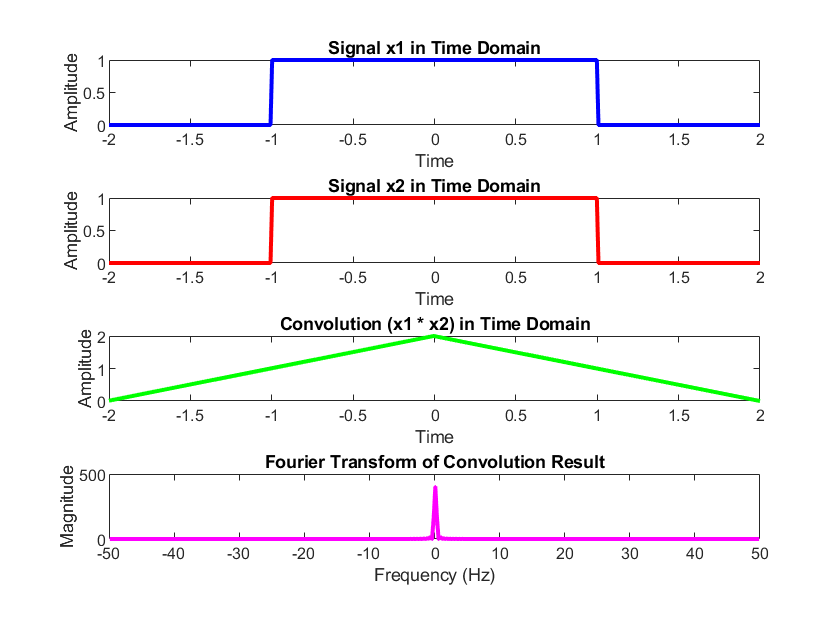

% Convolution property in Fourier transform

% Defining parameters
T = 1;          % Period of the rectangular function
t = linspace(-2*T, 2*T, 400); % Time vector with 400 points

% Original rectangular functions
x1 = rectangularPulse(-T, T, t);
x2 = rectangularPulse(-T, T, t);

% Convolution of x1 and x2 in the time domain
x_convolved = conv(x1, x2, 'same') * (t(2)-t(1)); % Scale by the sampling interval

% Fourier transform of x1 and x2
X1 = fftshift(fft(x1));
X2 = fftshift(fft(x2));

% Fourier transform of the convolution (Multiplication property)
X_convolved = X1 .* X2;

% Fourier transform of the convolution result
X_result_convolved = fftshift(fft(x_convolved));

% Frequency vector
Fs = 1/(t(2)-t(1)); % Sampling frequency
f = linspace(-Fs/2, Fs/2, length(t));

% Creating a new figure
figure;

% Plotting the original signals in the time domain
subplot(4,1,1);
plot(t, x1, 'b', 'LineWidth', 2);
title('Signal x1 in Time Domain');
xlabel('Time');
ylabel('Amplitude');

subplot(4,1,2);
plot(t, x2, 'r', 'LineWidth', 2);
title('Signal x2 in Time Domain');
xlabel('Time');
ylabel('Amplitude');

% Plotting the convolution in the time domain
subplot(4,1,3);
plot(t, x_convolved, 'g', 'LineWidth', 2);
title('Convolution (x1 * x2) in Time Domain');
xlabel('Time');
ylabel('Amplitude');

% Plotting the Fourier transform of the convolution result
subplot(4,1,4);
plot(f, abs(X_result_convolved), 'm', 'LineWidth', 2);
title('Fourier Transform of Convolution Result');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

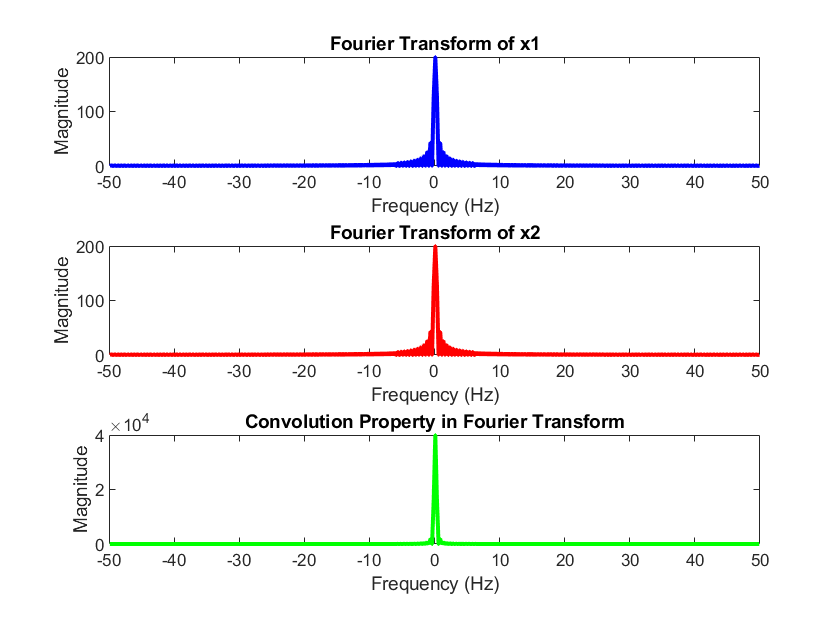


% Creating a new figure for the frequency domain
figure;

% Plotting the Fourier transforms
subplot(3,1,1);
plot(f, abs(X1), 'b', 'LineWidth', 2);
title('Fourier Transform of x1');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(3,1,2);
plot(f, abs(X2), 'r', 'LineWidth', 2);
title('Fourier Transform of x2');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plotting the Fourier transform of the convolution
subplot(3,1,3);
plot(f, abs(X_convolved), 'g', 'LineWidth', 2);
title('Fourier Transform of Convolution (X1 * X2)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Adjusting subplot layout
title('Convolution Property in Fourier Transform', 'FontSize', 14);